# ElasticPOST Tutorial

This is a short example of ElasticPOST in command mode.

## 3D crystal

1. Load data

load('test3D.mat');
CIJ = Cij(1:6, :);
S = inv(CIJ);

2. Calculate the Young's modulus along a line

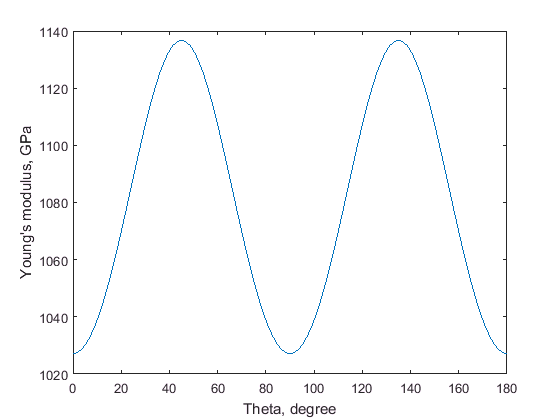

theta = 0:pi/100:pi;
phi = 0;
E = Young_3D(S, theta, phi);
theta = theta/pi*180;%To degree
plot(theta, E)
ylabel('Young''s modulus, GPa');
xlabel('Theta, degree');

3. Calculate the polycrystalline elastic constant and related properties

output = ElasticVRH3D(CIJ)

output =    1.0e+03 *

    0.4353    0.4353    0.4353    0.0000    0.0000    0.0000
    0.5228    0.5182    0.5205    0.0000    0.0000    0.0000
    1.1200    1.1130    1.1165    0.0000    0.0000    0.0000
    0.0932    0.0919    0.0926    0.0000    0.0000    0.0000
    0.0934    0.0920    0.0927    0.0000    0.0000    0.0000
    0.0952    0.0937    0.0945    0.0000    0.0000    0.0000
    0.0001    0.0001    0.0001    0.0000    0.0000    0.0000
    0.0008    0.0008    0.0008    0.0000    0.0000    0.0000


4. Plot 3D distribution of Young's modulu and shear modulu

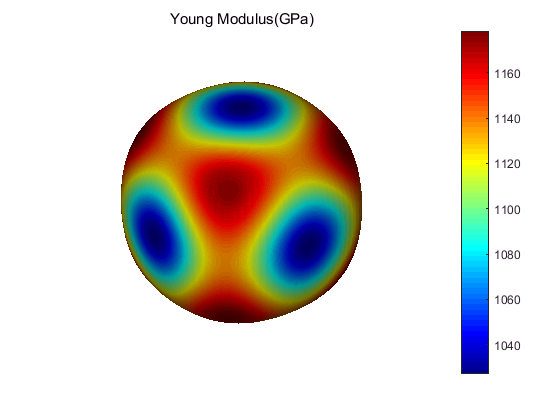

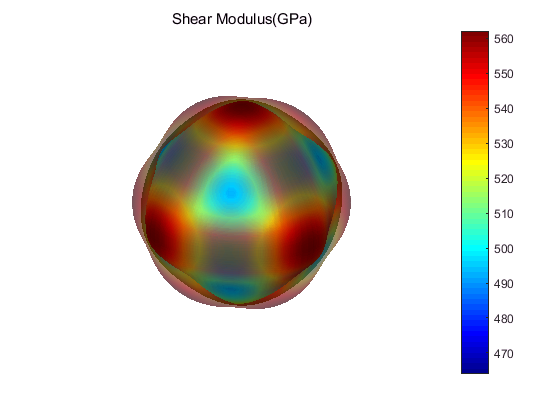

n = 100;
flag_save = 0; %save or not
flag_amm = 'All';
flag = {'E', 'G'};
ElasticPlot_3D(S, n, flag, flag_amm, flag_save, 'test');

5. Slice along the axis plane

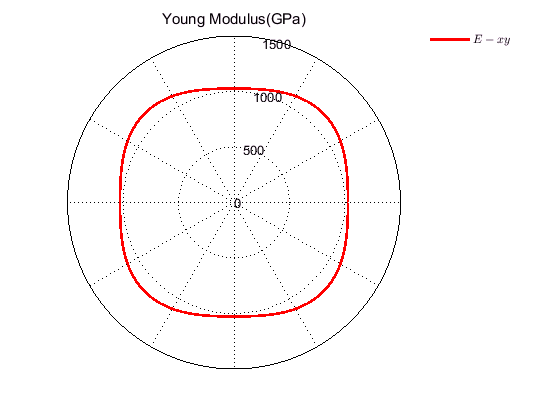

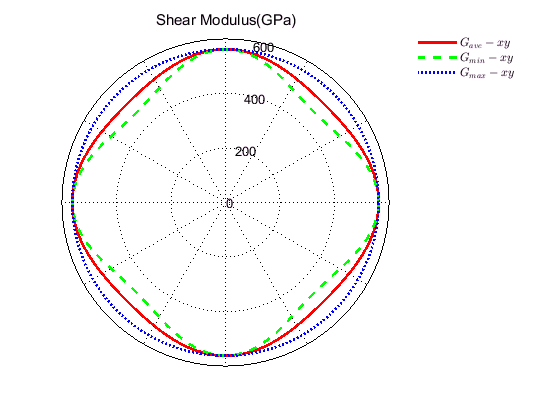

flag_plane = {'xy'};
ElasticPlot_2D(S, n, flag, flag_plane, flag_save, 'test');

6. Slice along any direction

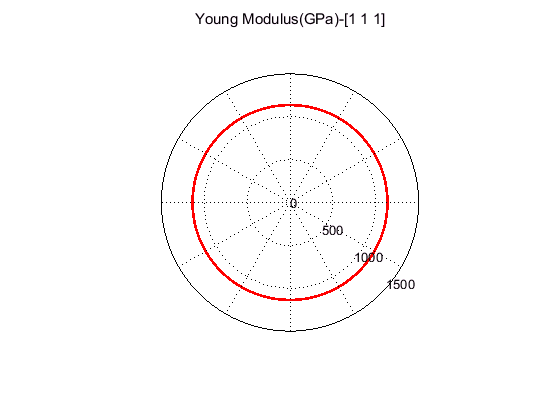

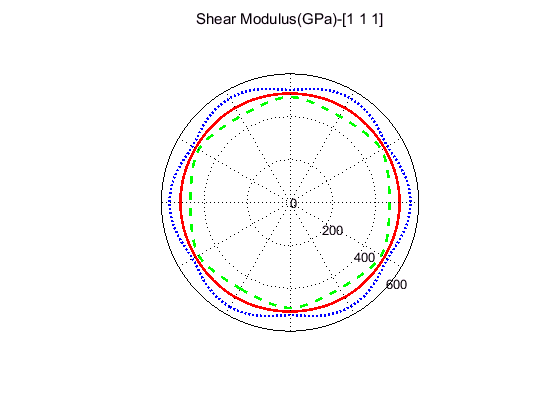

slice_plane = [1, 1, 1];
Plot_Slice(S, n, flag, slice_plane, flag_save, 'test');

7. Multi materials

filename = 'ExampleData.txt';
[Cij, ComName, State] = Elastic_Read(filename);

The row of data is not dividable by 6. The last 4 lines are negnected.
The format should be:
CIJ1Name(Optional)
CIJ1(6x6 or 3x3)
CIJ2Name(Optional)
CIJ2(The size is the same as CIJ1)
......
  
There are 8 CIJs.
 


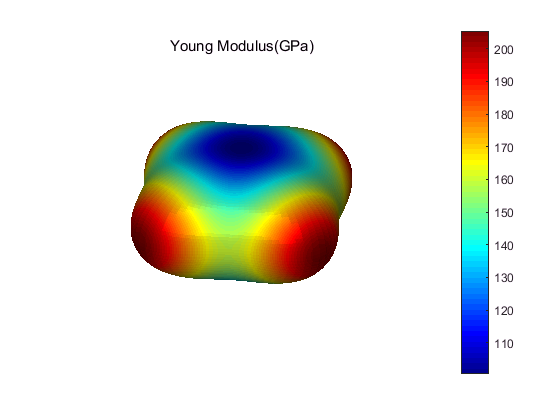

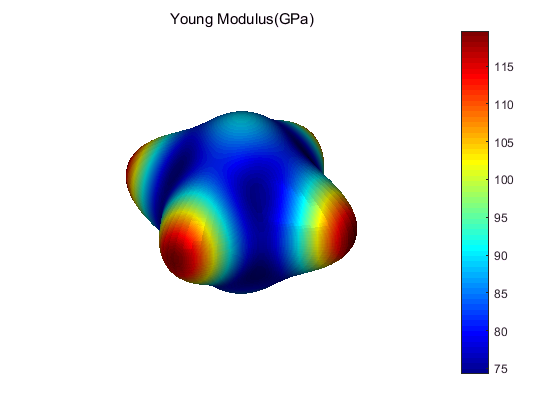

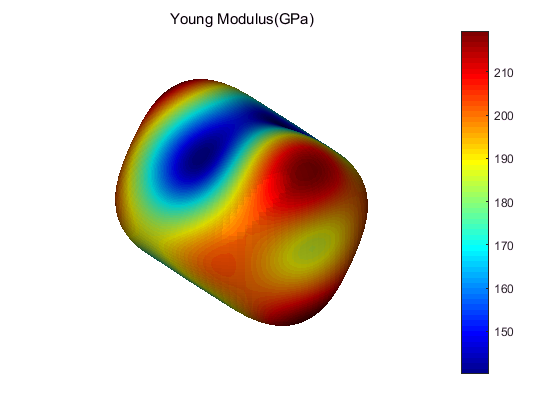

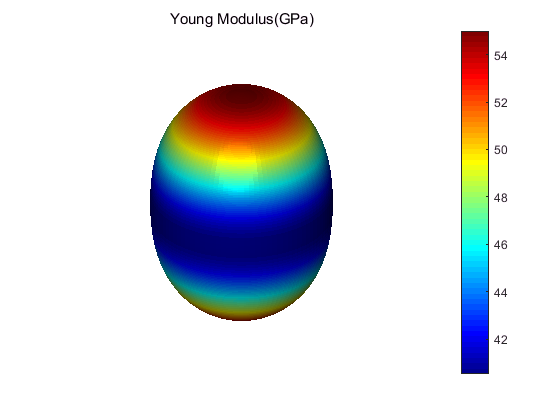

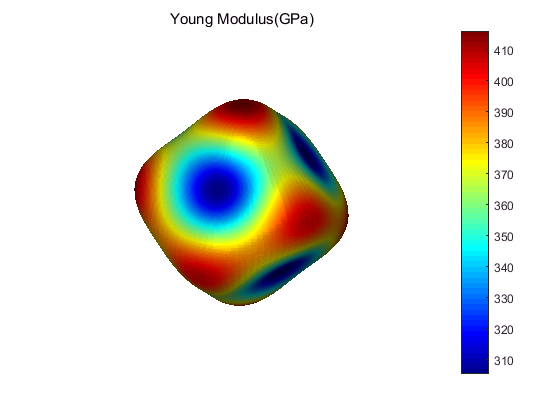

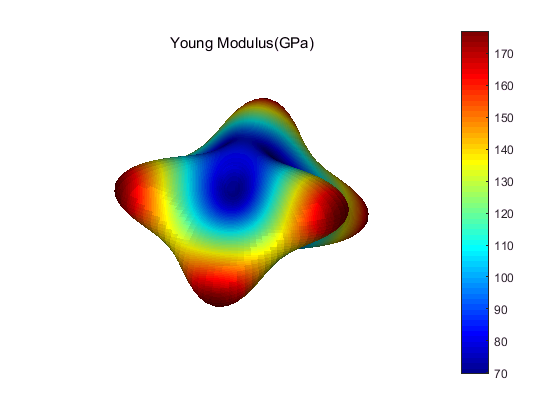

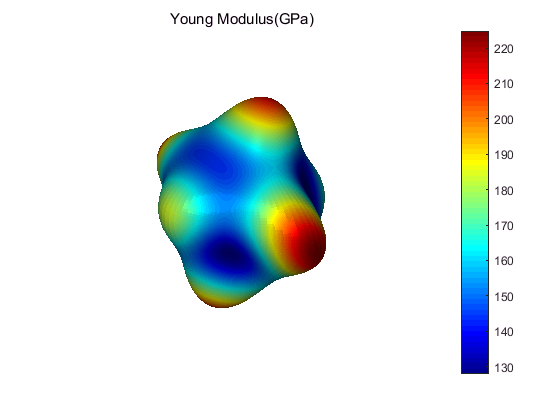

n_cij = size(Cij, 3);
flag = {'E'};
for i = 1:n_cij
    Si = inv(Cij(:, :, i));
    ElasticPlot_3D(Si, n, flag, flag_amm, flag_save, 'test');
end

## 2D crystal

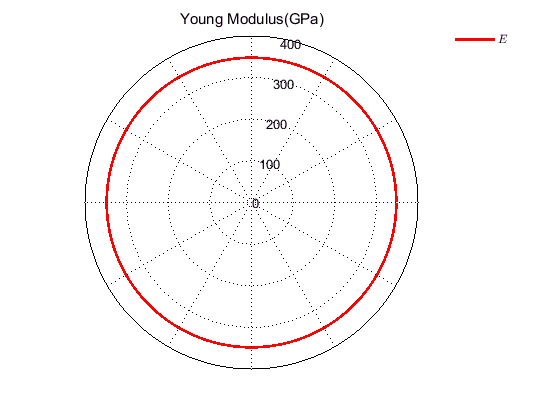

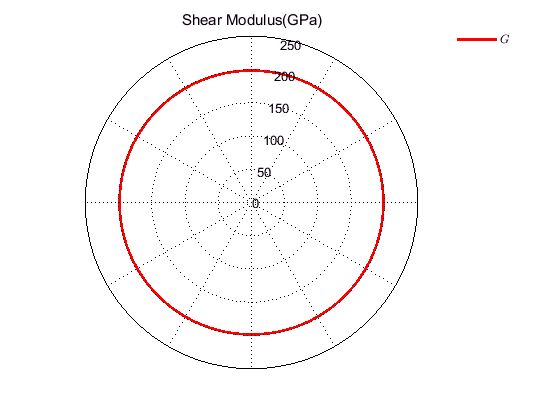

load('test2D.mat');
CIJ = Cij(10:12, :);
n = 200;
flag = {'E', 'G'};
S = inv(CIJ);
ElasticPlot_2DM(S, n, flag, 0, 'test')